# Question - 2 (PART- II)

% Clear workspace and command window
clear; clc; close all;
% For reproducibility
rng(27); 

## Load data

% Load data from the CSV file
raw_data = readtable("../../dataset/tesla_stock_price.csv");

% Input data
time_stamps = datetime(table2array(raw_data(:,1)),  "InputFormat", "dd-MM-yyyy"); % Timestamps 
stock_price = table2array(raw_data(:,2)); % Stock price

## Splitting the data

Since, the input is a Timeseries data, we consider the first 80% data for training and the last 20% data for testing

N = length(time_stamps);
% Compute the split index 
split_index = N-floor(N*0.2);
% Training data
X_train = time_stamps(1:split_index);
Y_train = stock_price(1:split_index);
% Testing data
X_test = time_stamps(split_index+1:N);
Y_test = stock_price(split_index+1:N);

## Visualize Data

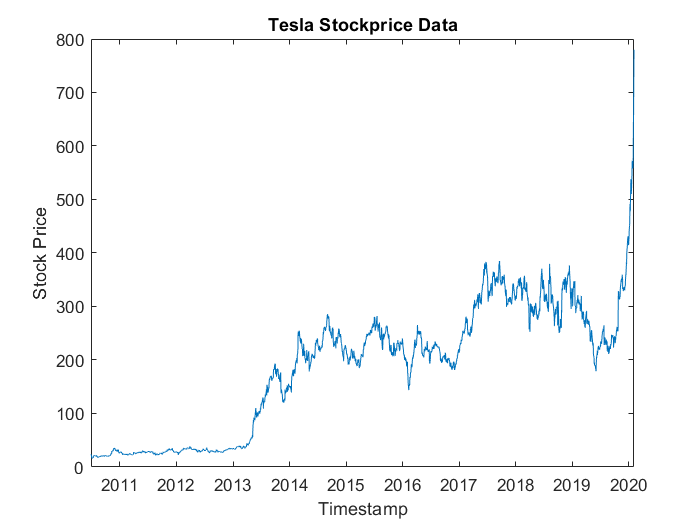

figure;
plot(time_stamps, stock_price)
title("Tesla Stockprice Data")
xlabel("Timestamp")
ylabel("Stock Price")

## Period Identification

We need to identify the period of the data to fix the frequency range for the Lomb Scale Periodogram. Let's us check the number of values collected for every year in the dataset.

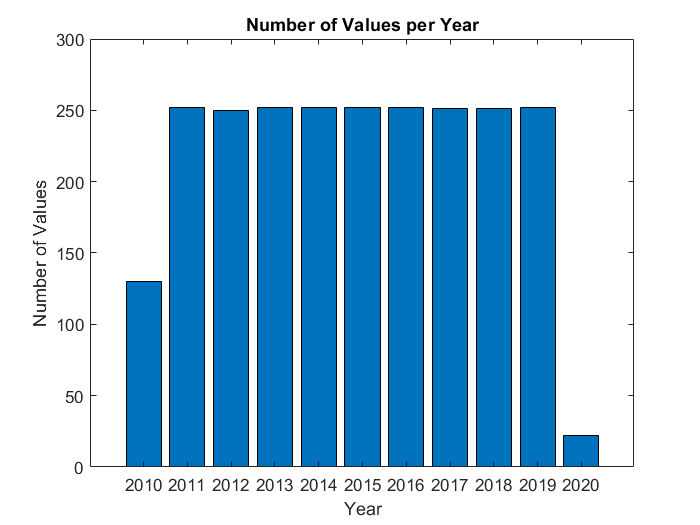

% Extract the year from the timestamps array
years = year(time_stamps);
% Get the unique years present in the data
unique_years = unique(years);
% Initialize a vector to store the counts for each year
year_counts = zeros(size(unique_years));
% Count the number of values for each year
for i = 1:length(unique_years)
    year_counts(i) = sum(years == unique_years(i));
end
% Create a bar graph
figure;
bar(unique_years, year_counts);
xlabel('Year');
ylabel('Number of Values');
title('Number of Values per Year');

Similarly for number of values per month in a year. 

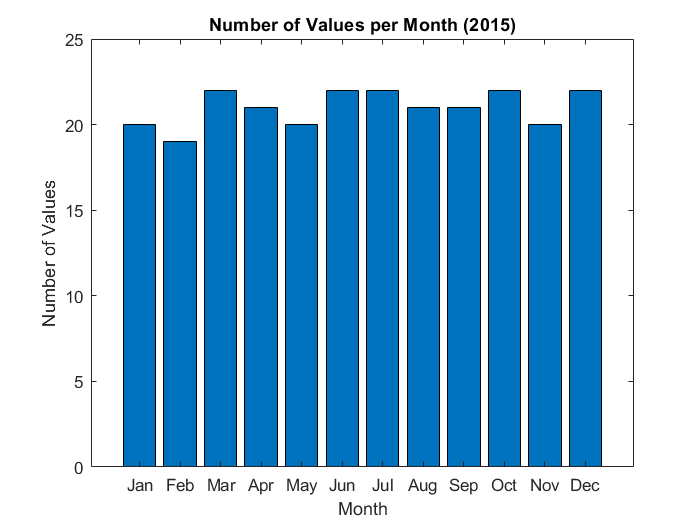

% Year of interest
year_of_interest = 2015; 
% Extract the year from the timestamps array
years = year(time_stamps);
% Filter the data for the specified year
idx = years == year_of_interest;
timestamps_filtered = time_stamps(idx);
% Count the number of values per month
months = month(timestamps_filtered);
counts = accumarray(months, 1);
% Create a bar graph
figure;
bar(counts);
xlabel('Month');
ylabel('Number of Values');
title(sprintf('Number of Values per Month (%d)', year_of_interest));
set(gca, 'XTick', 1:12, 'XTickLabel', {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec'});

Based on the above graphs, we can infer that the data is collected on the daily basis. The given dataset contains missing values for a few days in between. But almost all the years have about 70% of the data (i.e) nearly 250 data points per year. Therefore, the sampling is done daily. **Fs/2 = 365.**

## Preprocess Data

% Convert the DateTime array into double. We will consider the first
% timestamp as t=0
X_diff = convertTo(X_train, 'datenum')-convertTo(X_train(1), 'datenum');
fprintf("Series Length: %d", length(X_diff));

Series Length: 1933

fprintf("Final Value of the Series: %d", X_diff(end));

Final Value of the Series: 2803

As predicted the dataset has missing values. Let's construct a dataset with all time indices with the missing values as NaN. 

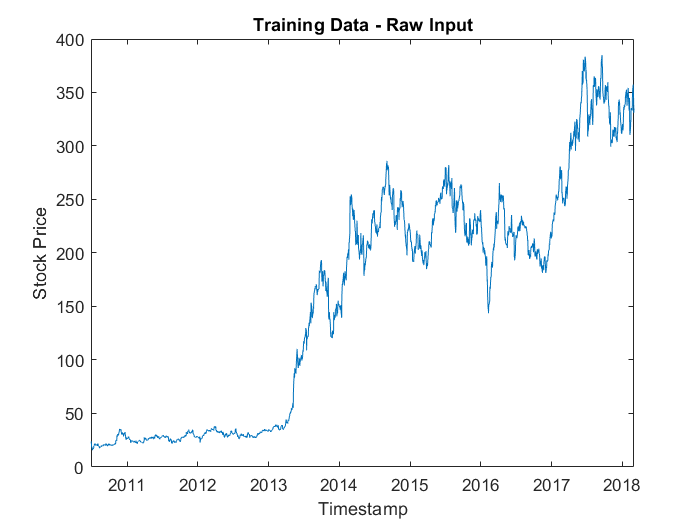

% Sampling frequency (Nyquist Rate, 2*F)
Fs = 730; % 365*2
M = X_diff(end)+1; % Length of the training data
time = (0:M-1)'/Fs; % Time Vector
signal = zeros(M, 1); % Signal placeholder
signal(:) = NaN; 
signal(X_diff+1) = Y_train; % Assign the value of the dataset

% Given Input training data
figure;
plot(X_train, Y_train);
title("Training Data - Raw Input");
xlabel("Timestamp");
ylabel("Stock Price");

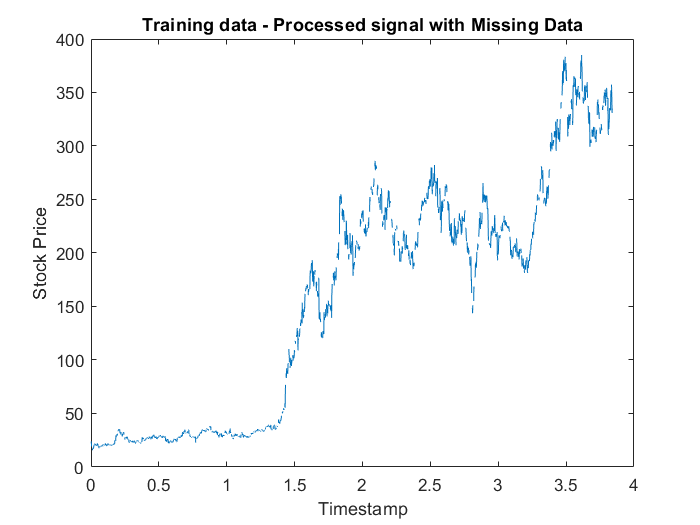

% Processed training data
figure;
plot(time, signal);
title("Training data - Processed signal with Missing Data");
xlabel("Timestamp");
ylabel("Stock Price");

## Lomb Scale Periodogram

learning_rate = 3e-2; % Learning rate
epochs = 150; % Epochs
% Compute Lomb Scale Periodogram
[F, P, C, A, B] = lomb_scale_periodogram(time, signal, learning_rate, epochs, 1500);

**Periodogram**

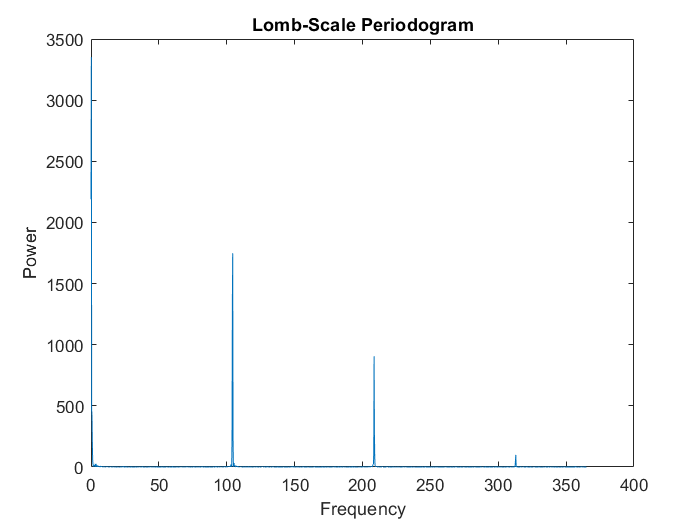

% Plot the periodogram
figure;
plot(F, P);
xlabel('Frequency');
ylabel('Power');
title('Lomb-Scale Periodogram');

**Cost History**

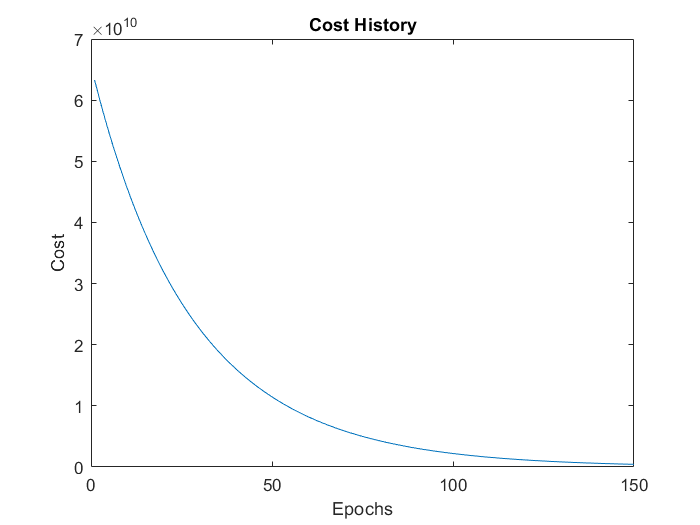

% Plot the cost history
figure;
plot(1:epochs, C);
xlabel('Epochs');
ylabel('Cost');
title('Cost History');

## Predictions

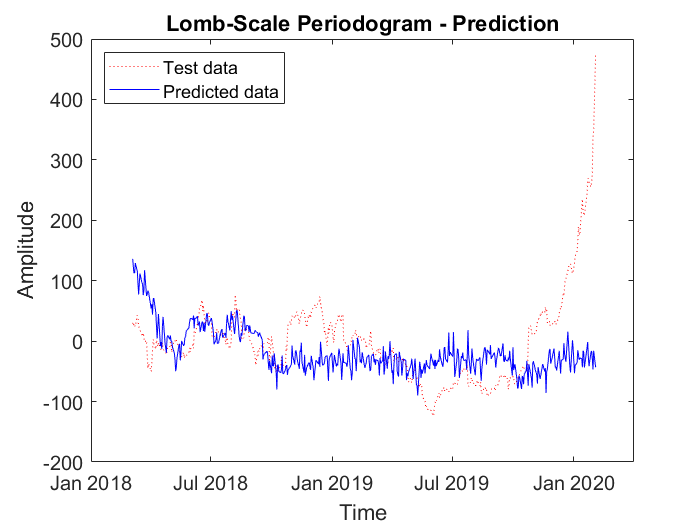

% Convert DateTime and double
X_range = convertTo(X_test, 'datenum')-convertTo(X_train(1), 'datenum');
time_t = X_range/Fs;

% Predict the signal with the periodogram outputs
% Only consider the frequencies for which the power is greater than 1
frequency = F(P>1);
y_hat_lsp = zeros(N-split_index, 1);
for i = 1:length(frequency)
    w = 2*pi*frequency(i);
    y_hat_lsp = y_hat_lsp + A(i)*cos(w*time_t) + B(i)*sin(w*time_t);
end

% Mean center the Test data
mean_value = mean(Y_test); % Compute mean
y = Y_test - mean_value; % Mean center the signal

% Plot the comparison
figure;
plot(X_test, y, 'r:');
hold on;
plot(X_test, y_hat_lsp, 'b-');
hold on;
legend('Test data', 'Predicted data', 'Location', 'NorthWest');
xlabel('Time', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('Lomb-Scale Periodogram - Prediction', 'FontSize', 14);
set(gca, 'FontSize', 12); % Set font size for axis labels and ticks
hold off;

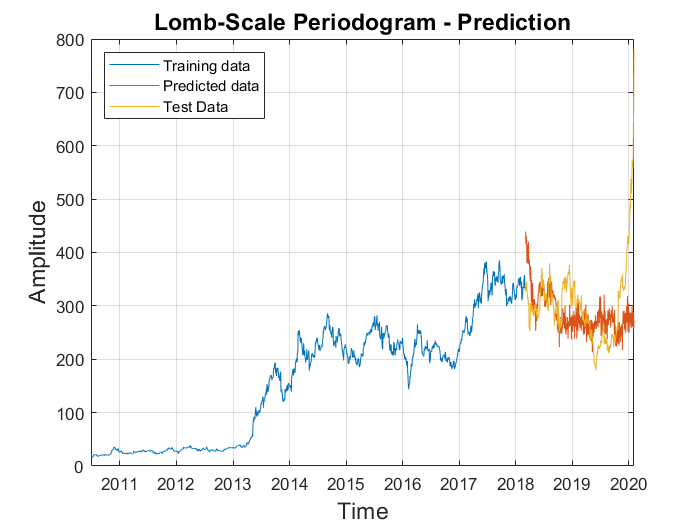

% Plot the whole series
figure
plot(X_train,Y_train);
hold on
plot(X_test,y_hat_lsp+mean(Y_test));
plot(X_test,Y_test);
legend('Training data', 'Predicted data', 'Test Data', 'Location', 'NorthWest');
xlabel('Time', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('Lomb-Scale Periodogram - Prediction', 'FontSize', 14);
grid on
hold off

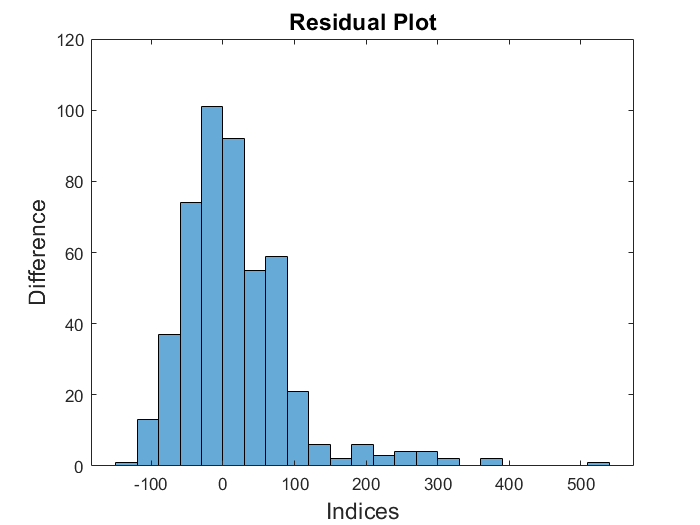

% Residual Plot
histogram(y-y_hat_lsp);
xlabel('Indices', 'FontSize', 14);
ylabel('Difference', 'FontSize', 14);
title('Residual Plot', 'FontSize', 14);

## ARIMA

% Order of the time series model
P = 2;
D = 0;
Q = 0;
% Initiate the model
model = arima(P,D,Q);

% Estimate coefficients for the model
[estModel,~,loglikehood, info] = estimate(model, Y_train)

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic     PValue 
                _________    _____________    __________    ________

    Constant      0.27206       0.39017        0.69727       0.48563
    AR{1}          1.0334      0.016587         62.301             0
    AR{2}       -0.034103      0.016578        -2.0571      0.039675
    Variance       24.094       0.40489         59.509             0



estModel =   arima with properties:

     Description: "ARIMA(2,0,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 2
               D: 0
               Q: 0
        Constant: 0.272057
              AR: {1.03336 -0.034103} at lags [1 2]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 24.0943

loglikehood = -5.8167e+03

info = struct with fields:
    exitflag: 2
     options: [1×1 optim.options.Fmincon]
           X: [4×1 double]
          X0: [4×1 double]


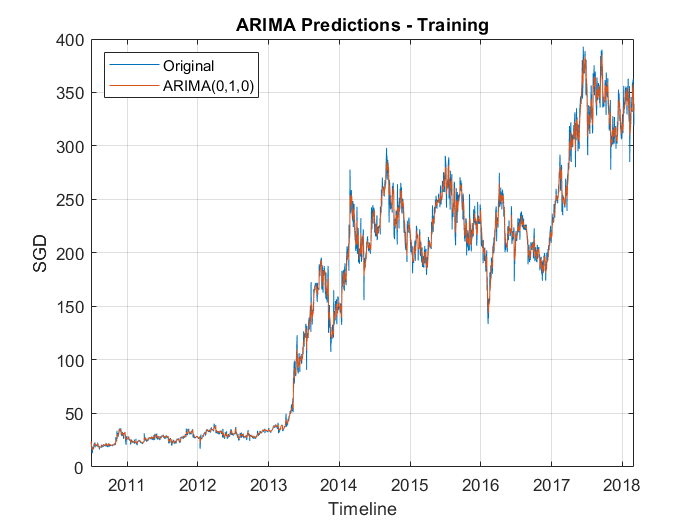

% View the predictive value
residual = infer(estModel, Y_train);
% Compute predictions for the training set
prediction = Y_train + residual;

% Plot the prediction
figure
plot(X_train, prediction);
hold on
plot(X_train, Y_train);
title('ARIMA Predictions - Training');
ylabel('SGD');
xlabel('Timeline');
legend('Original','ARIMA(0,1,0)','Location','northwest');
grid on
hold off

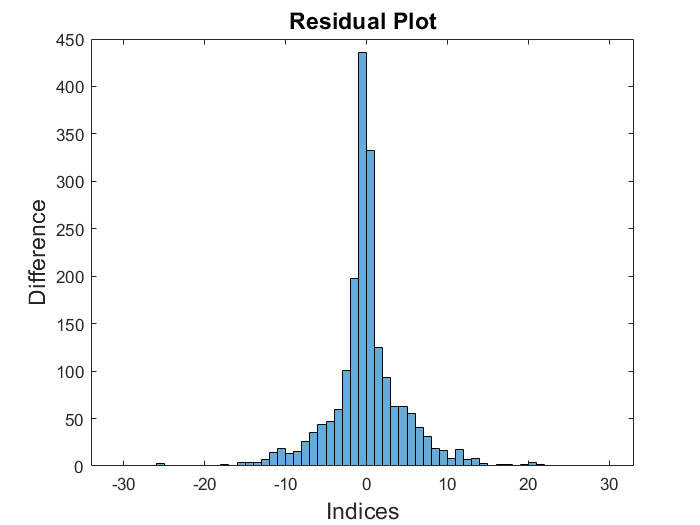

% View Resdsidual Histogram
histogram(residual)
xlabel('Indices', 'FontSize', 14);
ylabel('Difference', 'FontSize', 14);
title('Residual Plot', 'FontSize', 14);

**Predictions**

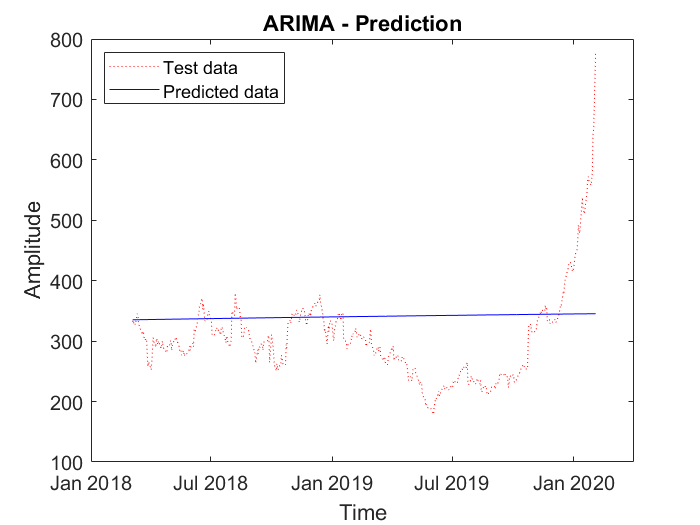

% Forecast the test data
len=length(Y_test);
y_hat_ari = forecast(estModel,len,'Y0',Y_train);

% Plot the comparison
figure;
plot(X_test, Y_test, 'r:');
hold on;
plot(X_test, y_hat_ari, 'b-');
hold on;
legend('Test data', 'Predicted data', 'Location', 'NorthWest');
xlabel('Time', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('ARIMA - Prediction', 'FontSize', 14);
set(gca, 'FontSize', 12); % Set font size for axis labels and ticks
hold off;

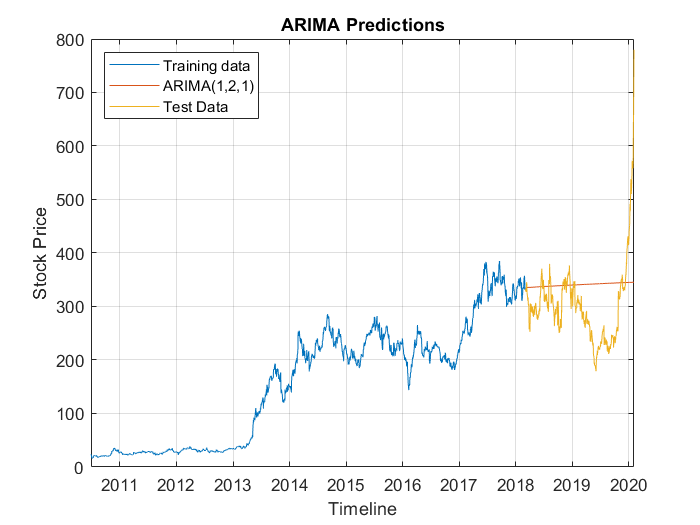

figure
plot(X_train,Y_train);
hold on
plot(X_test,y_hat_ari);
plot(X_test,Y_test);
title('ARIMA Predictions');
ylabel('Stock Price');
xlabel('Timeline');
legend('Training data','ARIMA(1,2,1)','Test Data','Location','northwest');
grid on
hold off

## Metrics

% Compute Metrics
[nmse1, mape1] = metrics(y, y_hat_lsp);
[nmse2, mape2] = metrics(Y_test, y_hat_ari);

**Original Signal vs Reconstructed Signal**

% Comparison Metrics
cmetrics = {'NMSE', 'MAPE'};
methods = {'LSP', 'ARIMA'};

% Display metrics
TM = table([nmse1 mape1]', [nmse2, mape2]', 'VariableNames', methods);
TMD = table(cmetrics', TM, 'VariableNames', {'Parameters', 'Metrics'});
disp(TMD);

    Parameters        Metrics     
                   LSP      ARIMA 
    __________    ________________

      'NMSE'      2.4063    1.2682
      'MAPE'      363.33     22.55

